## **Homework #6 Dit Dejphachon**

1. Plot the pressure reflection and transmission coefficients and the intensity reflection and transmission coefficients for normal incidence of a plane wave on a fluid-fluid boundary for 0 < r1/r2 < 10. Comment on the results for r1/r2 = 0, r1/r2 = 1, and r1/r2 → ∞.

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%            HW#1              %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%            HW#1              %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


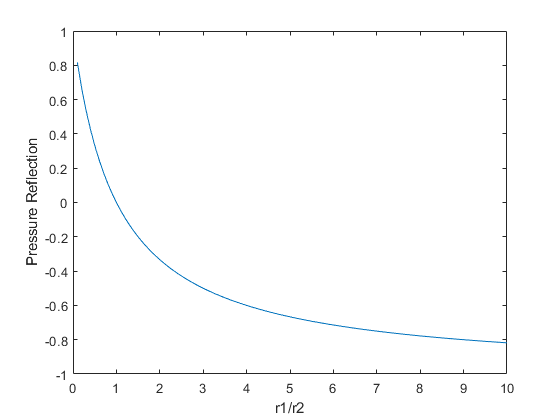



r1_r2 = linspace(0, 10, 100);
r2_r1 = 1./r1_r2;

% Pressure reflection and transmission coefficients
R = (r2_r1 - 1)./(r2_r1 + 1);
T = (2.*r2_r1)./(r2_r1 + 1);

figure
plot(r1_r2, R)
xlabel("r1/r2")
ylabel("Pressure Reflection")

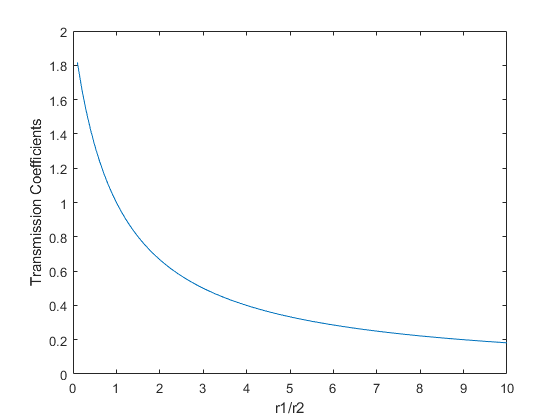


figure
plot(r1_r2, T)
xlabel("r1/r2")
ylabel("Transmission Coefficients")

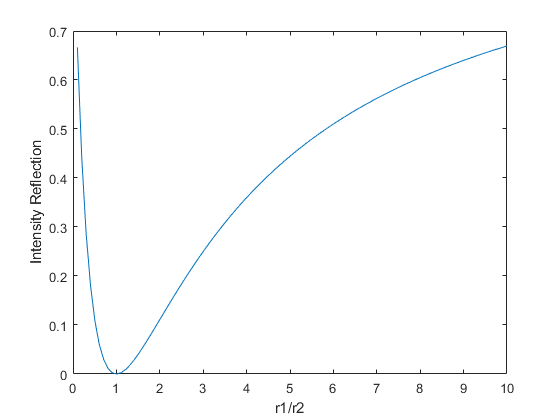


% The intensity reflection and transmission coefficients
R_I = ((r2_r1 - 1)./(r2_r1 + 1)).^2;
T_I = (4.*r2_r1)./(r2_r1 + 1).^2;

figure
plot(r1_r2, R_I)
xlabel("r1/r2")
ylabel("Intensity Reflection")

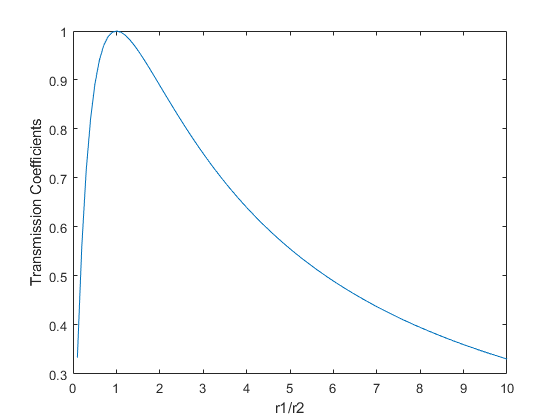


figure
plot(r1_r2, T_I)
xlabel("r1/r2")
ylabel("Transmission Coefficients")

2. 

(a) What must be the thickness of, and the speed of sound in, a plastic layer having a density of 1500 kg/m3 if it is to transmit plane waves at 20 kHz from water into steel with no reflection? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%            HW#2      a)        %%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%            HW#2      a)        %%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



f = 20000; %Hz
rho_plastic = 1500; %kg/m^3
rho_water = 998; %kg/m^3
rho_steel = 7700; %kg/m^3

c_water = 1481; %m/s
c_steel = 6100; %m/s

r1 = rho_water*c_water;
r3 = rho_steel*c_steel;

syms r2

equ_1 = 4/(2+(r2^2)/(r1*r3) + (r1*r3)/(r2^2)) == 1;

E = [equ_1];
R2 = vpasolve(E, r2);


% speed of sound in plastic layer
R2(3)

$$ans = 8332073.2630000319746948437267346$$


% thickness of plastic layer

c2 = R2(3)/rho_plastic;
L = c2/(4*f)

$$L = 0.069433943858333599789123697722789$$

(b) What would be the intensity reflection coefficient back into water for normally incident waves impinging on an infinitely thick layer of this plastic? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%            HW#2      b)        %%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%            HW#2      b)        %%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


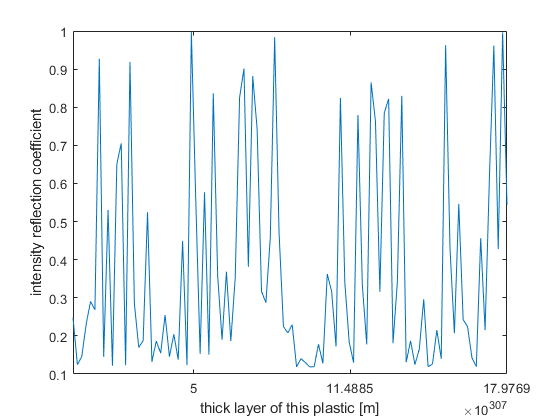


k2 = (2*pi*f)/c2;
L = linspace(0.1, realmax, 100);
r2 = R2(3);
T_I_1 = ((r3./r1) + (r1./r3)).*(cos(k2.*L).^2);
T_I_2 = (((r2.^2)/(r1.*r3)) + ((r1.*r3)./(r2.^2))).*(sin(k2.*L)).^2;
T_I = 4./ (2 + (T_I_1) + (T_I_2));

plot(L,T_I)

ylabel("intensity reflection coefficient")
xlabel("thick layer of this plastic [m]")

3. Given the task of maximizing the transmission of sound waves from water into steel, 

(a) what is the optimum characteristic impedance of the material to be placed between the water and the steel? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#3      a)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#3      a)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



rho_water = 998; %kg/m^3
rho_steel = 7700; %kg/m^3

c_water = 1481; %m/s
c_steel = 6100; %m/s

r_water = rho_water*c_water;
r_steel = rho_steel*c_steel;

% From

% we have to minimize the term with r2
% So, the deriviative of r2^2/(r1*r3) + r1*r3/r2^2 must be zero

syms r2

S = diff(r2^2/(r_water*r_steel) + r_water*r_steel/r2^2, r2);
R2 = vpasolve(S, r2);
R2 = R2(2)

$$R2 = 8332073.2630000319746948437267346$$

(b) What must be the density of, and sound speed in, a layer of 1 cm thickness that will produce 100% transmission at 20 kHz? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#3      b)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#3      b)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



f = 20e03;
L = 0.01;
syms n c2

omega = 2*pi*f;
k2 = omega/c2;

equ = k2 == (n - 0.5)*(pi/L);

% sound speed in the material
C2 = solve(equ, c2)

$$C2 = \frac{1}{\frac{n}{400}-\frac{1}{800}}$$


% density of the material
rho = R2/C2

$$rho = 20830.183157500079936737109316837\,n-10415.091578750039968368554658418$$

4. 

(a) As a function of 𝜃𝑖 , plot the amplitude and phase of the pressure reflection coefficient for the case c2 = c1 and 𝜌2 > 𝜌1 and identify any significant features. 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#4      a)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#4      a)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


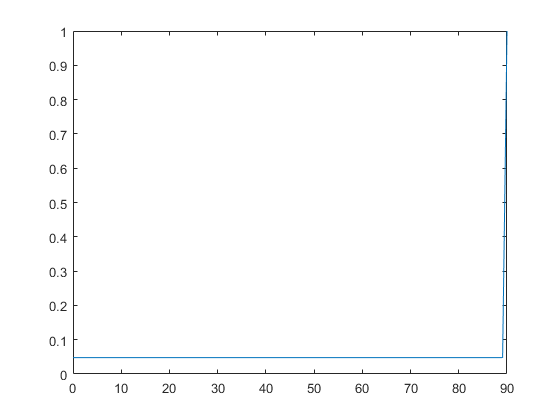


theta_i = linspace(0,90,100); % degree
theta_i = deg2rad(theta_i);
cos_theta_t = (1 - (sin(theta_i)).^2).^(0.5);

c_1 = 1;
c_2 = c_1;

rho_1 = 1;
rho_2 = rho_1*1.1;

r_1 = c_1*rho_1;
r_2 = c_2*rho_2;

R = ((r_2./r_1) - (cos_theta_t./cos(theta_i)))./ ((r_2./r_1) + (cos_theta_t./cos(theta_i)));

figure
theta_i = linspace(0,90,100); % degree

R_A = (R.^2).^(0.5);
plot(theta_i,R_A)

(b) Plot the amplitude and phase of the pressure reflection coefficient for the case 𝜌2 = 𝜌1 and 𝑐2 > 𝑐1 and identify any significant features. 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#4      b)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#4      b)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


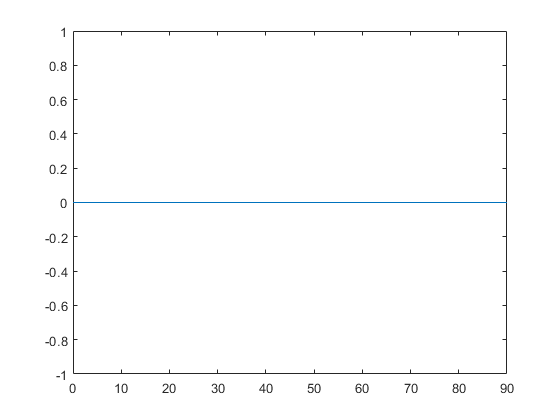


% phase
theta_i = linspace(0,90,100); % degree
theta_i = deg2rad(theta_i);
theta_c = deg2rad(90);

phi = 2.*atan((1).*sqrt(((cos(theta_c)./cos(theta_i)).^2)-1));

figure
theta_i = linspace(0,90,100); % degree
plot(theta_i,phi)

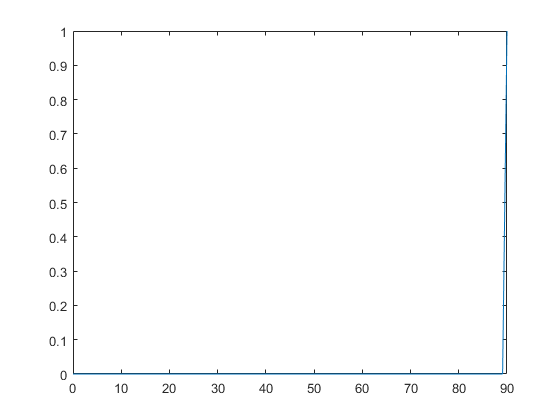


figure
theta_i = linspace(0,90,100); % degree
R = exp(1).^(1i.*phi);
plot(theta_i,R)

5. 

An acoustic tile panel is characterized by a normal specific acoustic impedance of 900 - j1200 Pa·s/m. 

(a) For what angle of incidence in air will the power reflection coefficient be a minimum? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#5      a)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#5      a)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


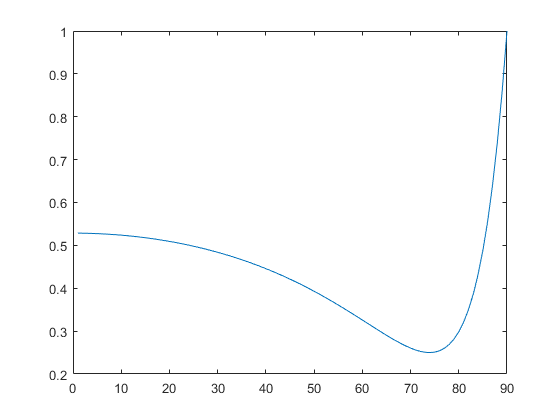


% normal specific acoustic impedance
z_n = 900 - 1200*1i;

r_n = 900;
x_n = -1200;
j_x_n = - 1200*1i;
r_1 = 415;

theta_i = linspace(1,90,90); % degree
theta_i = deg2rad(theta_i);
R = ((r_n - (r_1./cos(theta_i))) + j_x_n)./((r_n + (r_1./cos(theta_i))) + j_x_n);
figure
theta_i = linspace(1,90,90); % degree
plot(theta_i, abs(R).^2)

R_II = abs(R).^2;

xmin=find(R_II == min(R_II)) 

xmin = 74

(b) What is the power reflection coefficient for an angle of incidence of 80°? 

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#5      b)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#5      b)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



theta_i = 80;
theta_i = deg2rad(theta_i);
R = ((r_n - (r_1./cos(theta_i))) + j_x_n)./((r_n + (r_1./cos(theta_i))) + j_x_n);
R_II = abs(R).^2

R_II = 0.2984

(c) What is the power reflection coefficient for normal incidence?

disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%            HW#5      c)        %%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%            HW#5      c)        %%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



R = ((r_n - r_1) + j_x_n)/((r_n + r_1) + j_x_n);
R_II = abs(R).^2

R_II = 0.5286